# Placenta Test

run_id = 'test';

input_path = 'E:/2020-08-01-mPlac/';
useGPU = true;

data_dirs = dir(fullfile(input_path, "round1", "tile_*"))
data_dirs = struct2table(data_dirs);
data_dirs = natsort(data_dirs.name);
data_dirs = data_dirs(1:1)

Ndirs = numel(data_dirs);
upd = textprogressbar(Ndirs, 'updatestep', 1);

gpu_block = [1024 1024 25 4 6];

all_goodSpots = [];
all_goodReads = [];
all_score = [];
all_counts = 0;
    
starting = tic;
for p=1:Ndirs
    
    
    curr_data_dir = data_dirs{p};
    curr_out_path = fullfile(input_path, 'output', run_id, curr_data_dir)

    if ~exist(curr_out_path, 'dir')
        mkdir(curr_out_path)
    end
                
    sdata = new_STARMapDataset(input_path, 'useGPU', useGPU);
    sdata = sdata.LoadRawImages('sub_dir', curr_data_dir);
    sdata.rawImages = sdata.rawImages(1:1024, 1:1024, :,:,:);
    sdata = sdata.SwapChannels; % !!
    sdata = sdata.HistEqualize('Method', "inter_round");
    sdata = sdata.HistEqualize('Method', "intra_round");
    sdata = sdata.MorphoRecon('Method', "2d", 'radius', 3);
    
    sdata = sdata.test_GlobalRegistration;

    gpu_overlap = 0;
    gb_idx = BlockTest(sdata.rawImages, gpu_block, gpu_overlap);
    NgpuBlock = numel(gb_idx)
    
    tile_goodSpots = [];
    tile_goodReads = [];
    tile_score = [];
    tile_counts = 0;
    
    for i =1:NgpuBlock
        
        bdata_start = tic;
        gpu_idx = gb_idx{i}
        
        bdata = new_STARMapDataset(input_path, 'useGPU', useGPU);
        bdata = bdata.LoadDim(gpu_block);
        bdata.registeredImages = gpuArray(sdata.registeredImages(...
            gpu_idx(1,1):gpu_idx(1,2),...
            gpu_idx(2,1):gpu_idx(2,2),...
            :,:,:));
        
        bdata = bdata.LocalRegistration('Iterations', 50, 'AccumulatedFieldSmoothing', 0.5);
         
        % replace the old image 
        sdata.registeredImages(...
            gpu_idx(1,1):gpu_idx(1,2),...
            gpu_idx(2,1):gpu_idx(2,2),...
            :,:,:) = bdata.registeredImages;
        
        bdata = bdata.LoadCodebook;
        bdata = bdata.SpotFinding('Method', "barcode", 'qualityThreshold', 0.01, ...
                'volumeThreshold', 5, 'barcodeMethod', "iteration", 'showPlots', false);
        bdata = bdata.ReadsExtraction('showPlots',false, 'voxelSize', [1 1 1]); 
        bdata = bdata.ReadsFiltration('showPlots',false);
        
        block_offsets = [gpu_idx(2,1) - 1 gpu_idx(1,1) - 1 0]
        if size(bdata.goodSpots, 1) ~= 0
            block_offsets = repmat(block_offsets, size(bdata.goodSpots, 1), 1);
            bdata.goodSpots = bdata.goodSpots + int16(block_offsets);
        end
        
        % Update tile reads
        tile_goodSpots = [tile_goodSpots; bdata.goodSpots];
        tile_goodReads = [tile_goodReads; bdata.goodReads];
        tile_score = [tile_score; bdata.FilterScores];
        tile_counts = tile_counts + size(bdata.allSpots, 1);
        
        fprintf(sprintf("====Block %d Finished [time=%02f]====", i, toc(bdata_start)));
    end
    
%     % Save registered image
%     output_dir = fullfile(curr_out_path, 'registered_image');
%     if ~exist(output_dir, 'dir')
%        mkdir(output_dir);
%     end
%     new_SaveImg(output_dir, sdata.registeredImages);
    
%     % Save tile points 
%     save(fullfile(curr_out_path, strcat('goodPoints.mat')), 'tile_goodReads', 'tile_goodSpots');
    
    
%     all_score = [all_score; tile_score];
%     all_counts = all_counts + tile_counts;
    % reset(gpuDevice)
    
    
    upd(p);
end

sdata.jobFinished

toc(starting) / 3600

# Small tile test

run_id = 'test';

input_path = 'E:/2020-08-01-mPlac/';
useGPU = true;

data_dirs = dir(fullfile(input_path, "round1", "tile_*"))

data_dirs = 65×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


data_dirs = struct2table(data_dirs);
data_dirs = natsort(data_dirs.name);
data_dirs = data_dirs(1:1);

Ndirs = numel(data_dirs);
upd = textprogressbar(Ndirs, 'updatestep', 1);

Completed [                    ]   0% --:--:--



starting = tic;
for p=1:Ndirs
    
    curr_data_dir = data_dirs{p};
    curr_out_path = fullfile(input_path, 'output', run_id, curr_data_dir)

    if ~exist(curr_out_path, 'dir')
        mkdir(curr_out_path)
    end
                
    sdata = new_STARMapDataset(input_path, 'useGPU', useGPU);
    sdata = sdata.LoadRawImages('sub_dir', curr_data_dir);
    sdata.rawImages = sdata.rawImages(1:1024, 1:1024, :,:,:);
    sdata = sdata.SwapChannels; % !!
    sdata = sdata.HistEqualize('Method', "inter_round");
    sdata = sdata.HistEqualize('Method', "intra_round");
    sdata = sdata.MorphoRecon('Method', "2d", 'radius', 3);
    
    sdata = sdata.test_GlobalRegistration;
    sdata.registeredImages = gpuArray(sdata.registeredImages);
    sdata = sdata.LocalRegistration('Iterations', 50, 'AccumulatedFieldSmoothing', 0.5);
    
end

curr_out_path = 'E:\2020-08-01-mPlac\output\test\tile_1'

Pipeline Obj is generated...


====Loading raw images====
Loading round 1...[time = 37.62 s]
Loading round 2...[time = 38.69 s]
Loading round 3...[time = 37.61 s]
Loading round 4...[time = 38.05 s]
Loading round 5...[time = 37.97 s]
Loading round 6...[time = 36.89 s]
Collapsed to size 3072 by 3072 by 25
Collapsing round 1
Collapsing round 2
Collapsing round 3
Collapsing round 4
Collapsing round 5
Collapsing round 6
Raw image as 5-D array


====Swap Channels====
Channel 2 <==> Channel 3


====Histogram Equalization====
Method: inter_round
Equalizing channel 1
Equalizing channel 2
Equalizing channel 3
Equalizing channel 4


====Histogram Equalization====
Method: intra_round
Equalizing round 1
Equalizing round 2
Equalizing round 3
Equalizing round 4
Equalizing round 5
Equalizing round 6


====Morphological Reconstruction====
Method: 2d
Processing Round 1...[time = 1.04 s]
Processing Round 2...[time = 0.93 s]
Processing Round 3...[time = 0.90 s]
Processing Round 4...[time = 0.91 s]
Processing Round 5...[time = 0.92 s]
Processing Round 6...[time = 0.88 s]


====Global Registration====
Round 2 vs. Round 1 finished [time=3.853076]
Round 3 vs. Round 1 finished [time=3.221246]
Round 4 vs. Round 1 finished [time=3.118598]
Round 5 vs. Round 1 finished [time=3.201586]
Round 6 vs. Round 1 finished [time=3.103865]


====Local (Non-rigid) Registration====
[time = 0.00 s]
Round 2 vs. Round 1...[time = 24.58 s]
Round 3 vs. Round 1...[time = 23.67 s]
Round 4 vs. Round 1...[time = 23.44 s]
Round 5 vs. Round 1...[time = 23.60 s]
Round 6 vs. Round 1...[time = 23.51 s]


## Spot Finding test

sdata = sdata.LoadCodebook;

====Load Codebook====
doReverse: 1


====Spot Finding====
Method: barcode_test
Get barcodes for Round 1....Q: 0.91, C: 6492073[time = 4.07 s]
Get barcodes for Round 2....Q: 0.89, C: 7100644[time = 4.46 s]
Get barcodes for Round 3....Q: 0.88, C: 7457691[time = 4.43 s]
Get barcodes for Round 4....Q: 0.87, C: 6758226[time = 4.28 s]
Get barcodes for Round 5....Q: 0.87, C: 7009110[time = 4.36 s]
Get barcodes for Round 6....Q: 0.85, C: 6659848[time = 4.33 s]
The global quality score threshold for barcode calling is: 0.06 


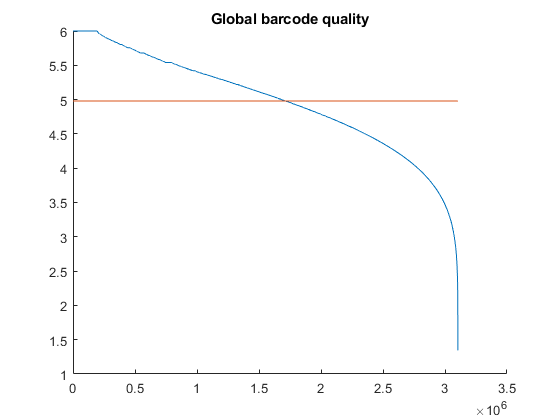

Iterate through clusters...[time = 49.96 s]


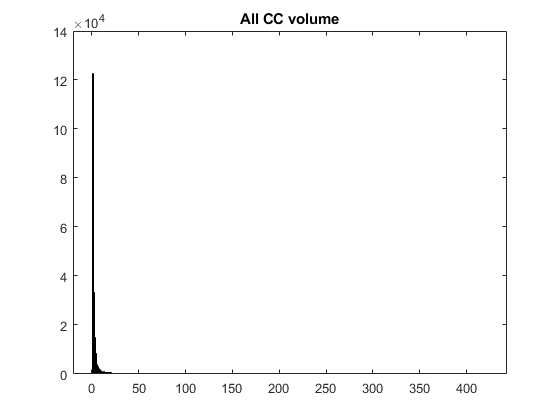

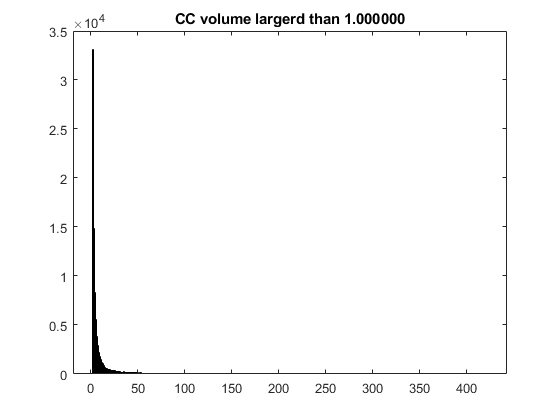

Number of spots found by barcode_test: 90599
[time = 52.05 s]


sdata = sdata.SpotFinding('Method', "barcode_test", 'qualityThreshold', 0.01, ...
        'volumeThreshold', 1, 'barcodeMethod', "iteration", 'showPlots', true);

% sdata = sdata.ReadsExtraction('showPlots',false, 'voxelSize', [2 2 1]); 
sdata = sdata.ReadsFiltration('showPlots',false);

====Reads Filtration====
Base in both ends: C --- C
Filtration Statistics:
1.000000 [90599 / 90599] percent of good reads are CNNNNNC
1.000000 [90599 / 90599] percent of good reads are in codebook
1.000000 [90599 / 90599] percent of CNNNNNC reads are in codebook


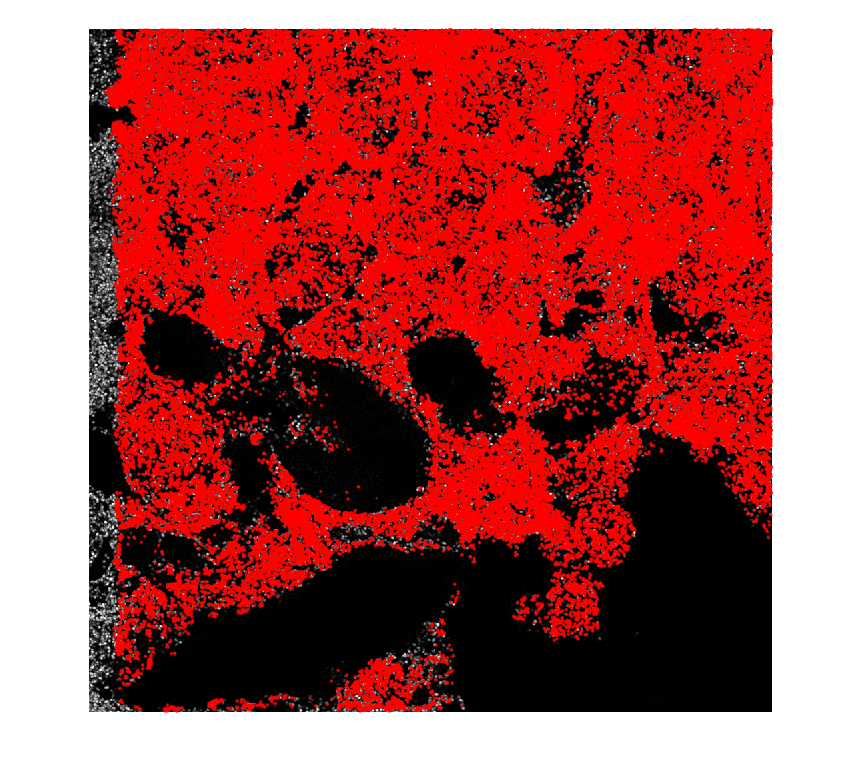

img = max(sdata.registeredImages(:,:,:,:,1), [], 4);
img = max(img, [], 3);
plot_centroids(sdata.goodSpots, img, 5)

sdata = sdata.LoadCodebook;
input_img = sdata.registeredImages;
seqTogene = sdata.seqToGene;
quality_factor = 0.01;
volume_threshold = 1;
showPlots = false;  

Nround = size(input_img, 5);
goodCodes = str2double(keys(seqTogene));
allSpots = [];
allReads = {};
basecsMat = [];
allScores = [];

local_threshold = quality_factor;

% get barcode for each pixel
[base_call_stack, quality_matrix, round_quality_matrix, ~] = GetBarcodes(input_img, local_threshold, false); % 

% get global quailty
base_call_qual = quality_matrix(quality_matrix ~= 0);
base_call_qual = reshape(base_call_qual, 1, numel(base_call_qual));

% get global quailty threshold
quality_threshold = quality_factor * max(quality_matrix, [], 'all');
fprintf('The global quality score threshold for barcode calling is: %4.2f \n', quality_threshold)

if showPlots
    figure
    hold on
    plot(sort(base_call_qual, 'descend'))
    plot(1:numel(base_call_qual), ones(numel(base_call_qual),1) * mean(base_call_qual))
    title('Global barcode quality')
    hold off
end


        
% iterate through correct barcode clusters
props = {'Volume'; 'Centroid'; 'VoxelIdxList'};
% props = {'Volume'; 'Centroid'; 'EquivDiameter'; 'VoxelIdxList'};

all_volume = []; 
fprintf('Iterate through clusters...')
tic;

iter_codes = goodCodes;

for c = 1:numel(iter_codes)

    curr_barcode = iter_codes(c); 

    curr_img = zeros(size(base_call_stack)); 
    curr_img(base_call_stack == curr_barcode & quality_matrix > quality_threshold) = 1; % global quality filtration 
    curr_img = logical(curr_img);


    curr_stats = regionprops3(curr_img, props);
    all_volume = [all_volume; curr_stats.Volume]; %% WARNING
    curr_valid_stats = curr_stats(curr_stats.Volume > volume_threshold, ["Centroid", "VoxelIdxList"]); % volume filtration
    curr_valid_cc = int16(curr_valid_stats.Centroid);
    if ~isempty(curr_valid_cc)    
        Nspots = size(curr_valid_cc, 1);
        allSpots = [allSpots; curr_valid_cc]; %% WARNING
        curr_barcode = Colorseq2Str(curr_barcode);
        curr_read = repelem({curr_barcode}, Nspots, 1);
        allReads = [allReads; curr_read];
        curr_mat = reshape(curr_barcode, [Nround, 1]);
        curr_mat = arrayfun(@str2double, curr_mat);
        curr_mat = repmat(curr_mat', [Nspots, 1]);
        basecsMat = [basecsMat; curr_mat];
        
        for i=1:Nspots
            curr_spot = curr_valid_stats.VoxelIdxList{i};
            [row, col, z] = ind2sub(size(base_call_stack), curr_spot);
            curr_score = round_quality_matrix(row, col, z, :);
            curr_score = reshape(curr_score, [numel(row) 6]);
            curr_score = mean(curr_score)
            
        end
    end

end


fprintf(sprintf('[time = %.2f s]\n', toc));

## Barcode method test

% get barcode for each pixel
props = {'Volume'; 'Centroid'; 'VoxelIdxList'};
[base_call_stack, quality_matrix, barcodes] = GetBarcodes(sdata.registeredImages, 0.01, false); % 

iter_codes = barcodes;
% iter_codes = str2double(keys(sdata.seqToGene));

for c = 1:numel(iter_codes)
% for c = 1:1

    curr_barcode = iter_codes(c); 
   
    curr_img = zeros(size(base_call_stack)); 
    curr_img(base_call_stack == curr_barcode & quality_matrix > 0.01) = 1; % global quality filtration 
    curr_img = logical(curr_img);


    curr_stats = regionprops3(curr_img, props);

    curr_remove_cc = curr_stats(curr_stats.Volume <= 15, "VoxelIdxList"); % volume filtration
    curr_remove_cc = table2array(curr_remove_cc);
    curr_remove_cc = vertcat(curr_remove_cc{:});
    base_call_stack(curr_remove_cc) = 0;

        
end


fname = fullfile(input_path, 'output/test/base_call_stack_filtered.tif');

output_stack = uint32(base_call_stack);
saveastiff(output_stack, fname);

## DAPI Nissl registration test

% dapi & nissl registration 
input_path = 'E:/2020-08-01-mPlac/';
tic
cell_path = fullfile(input_path, 'dapi_nissl', 'tile_1')
cell_files = dir(fullfile(cell_path, '*.tif'))

cell_imgs = cell(3, 1);
% Load all channels
for c=1:3 
    curr_path = strcat(cell_files(c).folder, '/', cell_files(c).name);

    curr_img = new_LoadMultipageTiff(curr_path, 'uint8', 'uint8', false);
    
    cell_imgs{c} = curr_img(1:1024, 1:1024, :);
end

old_imgs = cell_imgs;

ref_round = gpuArray(sdata.rawImages(:,:,:,:,1));
fix = max(ref_round, [], 4);

params = DFTRegister3D(fix, cell_imgs{3}, false);
for c=1:3
    curr_reg = DFTApply3D(gpuArray(cell_imgs{c}), params, false);
    cell_imgs{c} = uint8(gather(curr_reg));
end

fprintf(sprintf('[time = %.2f s]\n', toc));

img = max(gather(fix), [], 3);
img2 = max(cell_imgs{3}, [], 3);
img3 = max(cell_imgs{1}, [], 3);
img4 = max(cell_imgs{2}, [], 3);

figure
imshowpair(img, img2)

figure
imshowpair(img, img3)

figure
imshowpair(img, img4)

plot_centroids(sdata.goodSpots, img3)

## Preprocessing test

rawImages = sdata.rawImages;
before = {};
after = {};

for r=1:6
    for c=1:4
        img = rawImages(:,:,:,c,r);
        before{end+1} = max(img, [], 3);   
    end
end

figure
montage(before, 'Size', [6 4], "BorderSize", [5 5])


rawImages = new_EqualizeHist3D(rawImages, 'inter_round');
rawImages = new_EqualizeHist3D(rawImages, 'intra_round');
rawImages = new_MorphologicalReconstruction(rawImages, "2d", 'radius', 3);

for r=1:6
    for c=1:4
        img = rawImages(:,:,:,c,r);
        after{end+1} = max(img, [], 3); 
    end
end

figure
montage(after, 'Size', [6 4], "BorderSize", [5 5])

% show round 2 
r2 = max(rawImages(:,:,:,:,2), [], 4);
r2_max = max(r2, [], 3);

figure
imshow(r2_max)

% show round 2 
r2 = max(rawImages(:,:,:,:,2), [], 4);
r2_max = max(r2, [], 3);

figure
imshow(r2_max)
